## Data Setup

We're using Fastion-MNIST again, data prep is much the same as last time.

filelist = dir('C:\Users\arkar\Downloads\ENN543_Assignment2_Data\Q2\UTKFace\UTKFace\*.jpg');
targetsize = 64;
images = zeros(targetsize,targetsize,1,length(filelist));
ages = zeros(length(filelist),1);
gender = zeros(length(filelist),1);
race = zeros(length(filelist),1);

for i=1:length(filelist)
    imgs = imresize(rgb2gray(imread(strcat(filelist(i).folder, "/", filelist(i).name))), [targetsize, targetsize]);
    images(:,:,:,i) = imgs;
    values = split(filelist(i).name, '_');
    ages(i) = double(string(values(1)));
    gender(i) = double(string(values(2)));
    race(i) = double(string(values(3)));
end

rng(4)
idx=randsample(1:length(ages),round(length(ages)*0.8),'false');
ages_train=ages(idx,:);
ages_test=ages;
ages_test(idx,:)=[];

data_to_train=reshape(images, [64*64, length(images)])';

faces_train=data_to_train(idx,:);
faces_test=data_to_train;
faces_test(idx,:)=[];

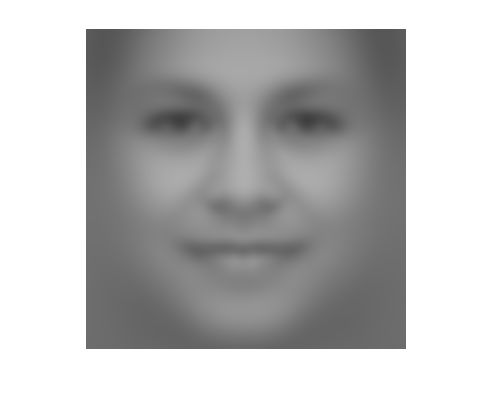

meanface=mean(faces_train);
figure
imshow(imresize(reshape(meanface,[64,64])/255,5))

faces_train=faces_train-meanface(:)';
faces_test=faces_test-meanface(:)';


[coeff,score,latent,tscores,explained,mu]=pca(faces_train,'Centered',false);

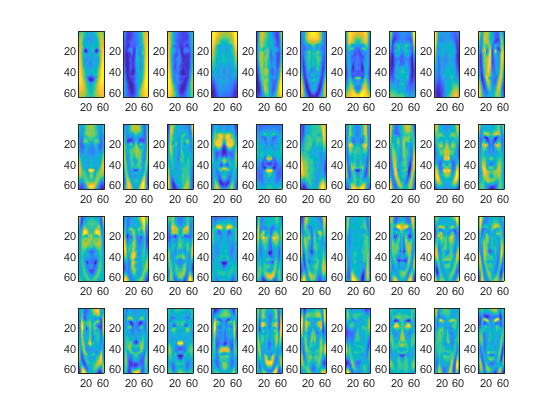

figure
visr = 4;
visc = 10;
count = 1;
for r=1:visr
    for c=1:visc
        subplot(visr, visc, count)
        imagesc(reshape(coeff(:,count), [64, 64]))
        count = count + 1;
    end
end

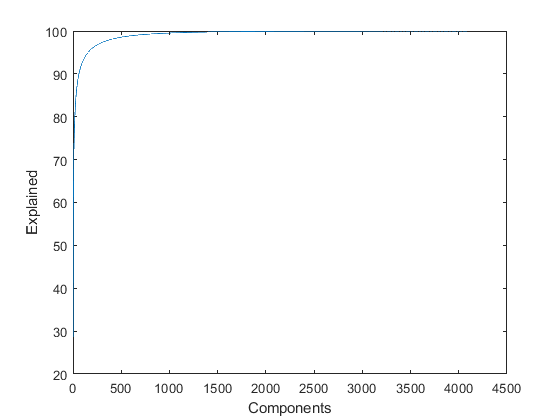

figure
plot(cumsum(explained))
xlabel('Components')
ylabel('Explained')

min(find(cumsum(explained) > 90))

ans = 62

min(find(cumsum(explained) > 95))

ans = 157

min(find(cumsum(explained) > 99))

ans = 647

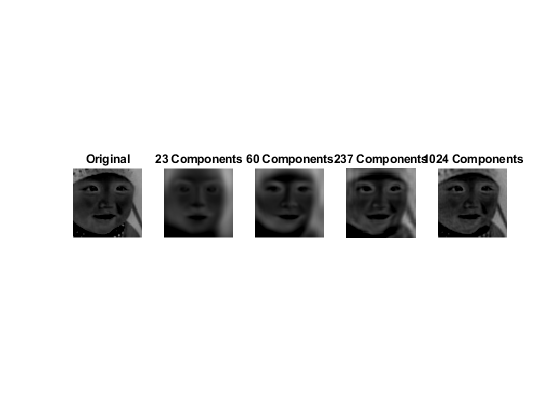

figure
subplot(1,5,1)
imshow(reshape(faces_train(120,:), [64, 64])/255)
title('Original')
subplot(1,5,2)
imshow(reshape(coeff(:,1:23)*score(120,1:23)', [64, 64])/255)
title('23 Components')
subplot(1,5,3)
imshow(reshape(coeff(:,1:60)*score(120,1:60)', [64, 64])/255)
title('60 Components')
subplot(1,5,4)
imshow(reshape(coeff(:,1:237)*score(120,1:237)', [64, 64])/255)
title('237 Components')
subplot(1,5,5)
imshow(reshape(coeff(:,1:1024)*score(120,1:1024)', [64, 64])/255)
title('1024 Components')

coeff_90 = coeff(:, 1:23);
score_90 = score(:, 1:23);

new_face = faces_test(1,:)*coeff_90;

distance = sqrt(sum((score_90 - new_face).^2, 2));
[mindist, idx] = min(distance)

mindist = 1.7648e+03

idx = 1441

ages_train(1441)

ans = 41

ages_test(41)

ans = 116


knn_90 = fitcknn(score_90, ages_train, 'NumNeighbors', 20)

knn_90 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1×103 double]
           ScoreTransform: 'none'
          NumObservations: 18966
                 Distance: 'euclidean'
             NumNeighbors: 20


  Properties, Methods


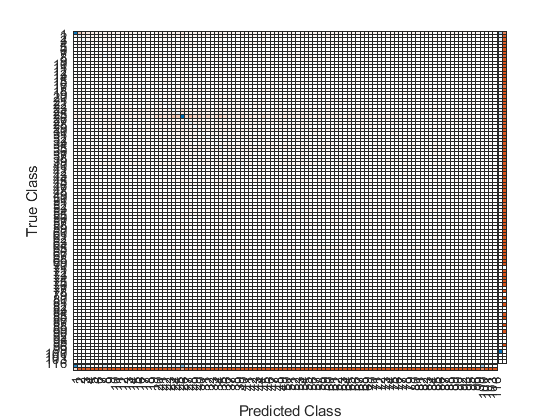

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [99×99 double]
         ClassLabels: [99×1 double]

  Show all properties


cknn_95 = fitcknn(score(:, 1:60), ages_train, 'NumNeighbors', 20);
cknn_px = fitcknn(faces_train, ages_train, 'NumNeighbors', 20);
classify_90 = knn_90.predict(faces_test*coeff_90);
classify_95 = cknn_95.predict(faces_test*coeff(:, 1:60));
classify_px = cknn_px.predict(faces_test);
figure
confusionchart(classify_90, ages_test,'RowSummary','row-normalized','ColumnSummary','column-normalized')

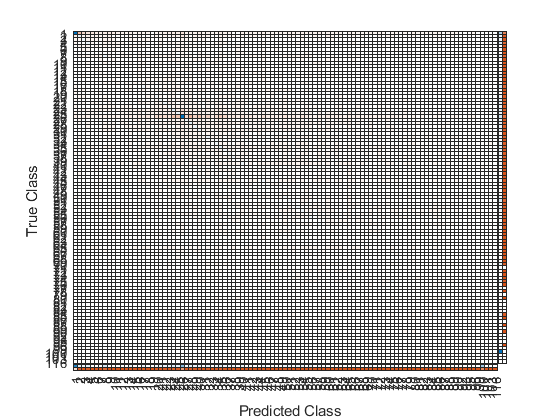

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [99×99 double]
         ClassLabels: [99×1 double]

  Show all properties


figure
confusionchart(classify_95, ages_test,'RowSummary','row-normalized','ColumnSummary','column-normalized')

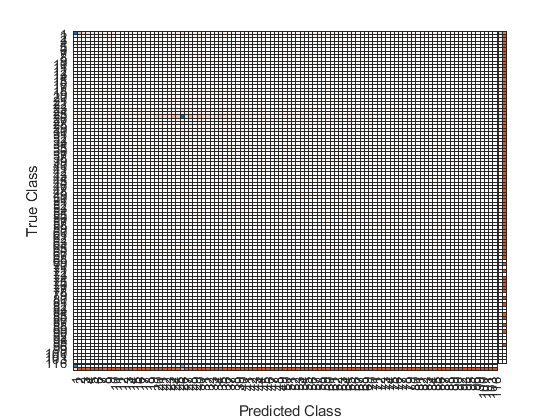

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [99×99 double]
         ClassLabels: [99×1 double]

  Show all properties


figure
confusionchart(classify_px, ages_test,'RowSummary','row-normalized','ColumnSummary','column-normalized')